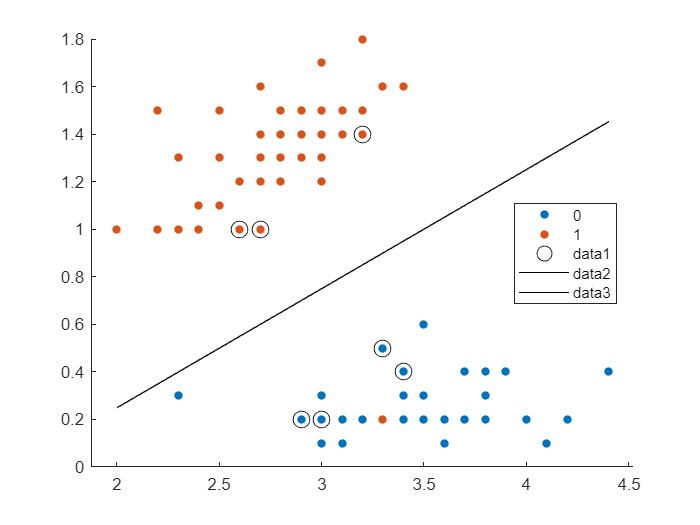

%Support Vector Machine
load fisheriris.mat;
X = meas(1:100,[2 4]);
y = zeros(100, 1);
y(50:100) = 1;
X_train = X([1:40, 51:90], :);
y_train = y([1:40, 51:90], :);
X_test = X([41:50, 91:100], :);
y_test = y([41:50, 91:100], :);

svmmodel = fitcsvm(X_train,y_train);
sv = svmmodel.SupportVectors;
hold on
gscatter(X(:,1),X(:,2),y)
plot(sv(:,1),sv(:,2),'ko','MarkerSize',10)
a = - svmmodel.Beta(1)/svmmodel.Beta(2);
b = - svmmodel.Bias/svmmodel.Beta(2);
Y = a.*X_train + b;
plot(X_train,Y,'k-')


y_predict = predict(svmmodel,X_test);
auc = sum(y_predict == y_test)/length(y_test)*100;
fprintf('%d\n', auc)

95
